clear all
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [9, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm", "Var5"];
opts.SelectedVariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm"];
opts.VariableTypes = ["double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var5", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var5", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("C:\Matlab\Matlab\Mathias\Adv udmat\Opgave 2\Stress_data.csv", opts);


data = table2array(tbl)

data = 1.0e+03 *

    0.0010    0.0034    0.0037    0.0458
    0.0020    0.0032    0.0037    0.0458
    0.0030    0.0030    0.0036    0.0458
    0.0040    0.0028    0.0036    0.0458
    0.0050    0.0026    0.0035    0.0458
    0.0060    0.0025    0.0034    0.0458
    0.0070    0.0023    0.0034    0.0458
    0.0080    0.0022    0.0033    0.0458
    0.0090    0.0021    0.0032    0.0458
    0.0100    0.0020    0.0032    0.0458


Y_data = data(:,4)

Y_data =    45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700



% data3 = data((data(:,1)<N_D) && (data(:,3)==0))

data_sort = [];
Y_line = 45.77

Y_line = 45.7700


for i = 1:length(data(:,1))
    if Y_data(i) == Y_line
        data_sort(end+1,2:3) = data(i,2:3);
    end
end


sigma = data_sort(:,2)

sigma =     3.4000
    3.2000
    3.0000
    2.8000
    2.6000
    2.5000
    2.3000
    2.2000
    2.1000
    2.0000


x = data_sort(:,3)

x =     3.7500
    3.6875
    3.6250
    3.5625
    3.5000
    3.4375
    3.3750
    3.3125
    3.2500
    3.1875


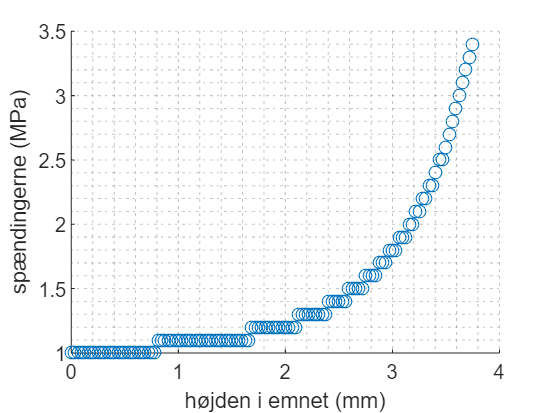


scatter(x, sigma)
% plot(x, sigma)
xlabel("højden i emnet (mm)")
ylabel("spændingerne (MPa)")
grid('minor')

F = 100; %N
A = pi*max(x)^2;
sigma_k = sigma %Fe spændingerne

sigma_k =     3.4000
    3.2000
    3.0000
    2.8000
    2.6000
    2.5000
    2.3000
    2.2000
    2.1000
    2.0000


sigma_n = F/A

sigma_n = 2.2635


K_t = sigma_k/sigma_n

K_t =     1.5021
    1.4137
    1.3254
    1.2370
    1.1486
    1.1045
    1.0161
    0.9719
    0.9278
    0.8836


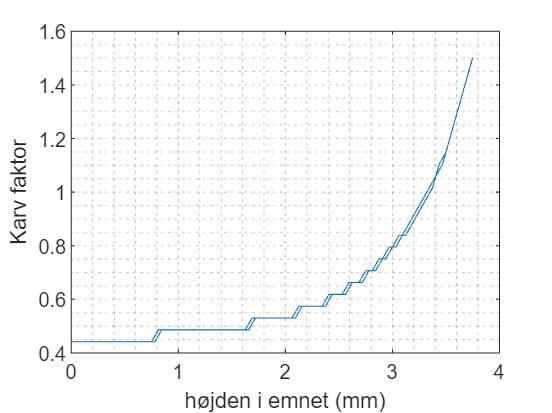

plot(x,K_t)
xlabel("højden i emnet (mm)")
ylabel("Karv faktor")
grid('minor')